## Eksamenssæt E2023

### Opgave 1: Sandsynlighedsregning

En produktionsvirksomhed har implementeret et automatisk inspektionssystem på en af deres produktionslinjer. Inspektionssystemet leder efter produktionsfejl i de fremstillede emner og foretages ved realtids billedanalyse af billeder indsamlet af hver emne. Hvis inspektionssystemet finder en produktionsfejl på et emne, frasorteres dette automatisk. 

I en intern test af inspektionssystemet blev emner med kendt tilstand (fejl / ikke-fejl) kørt igennem systemet, hvoraf der var fejl på 10% af emnerne. Inspektionssystemet havde efter testen frasorteret 12% af emnerne. Manuel inspektion af de frasorterede emner viste, at der var fejl i 68% af disse. 

**a) Definer de relevante hændelser og skitser tilhørende Euler/Venn diagram.**

Ud fra teksten ved vi at emnerne enten kan være frasorteret eller ej.

Yderligt ved at vi også at emnerne kan enten være med fejl eller fejlfrie.

Så vi har de 2 grupperinger og dermed en kombination på 4 hændelser.

Fejl + frasorteret (Sensitivitet)

Fejl + ikke-frasorteret (Type 2 fejl?)

fejlfri + frasorteret (Type 1 fejl?)

Fejlfri + ikke-frasorteret (Specificitet)

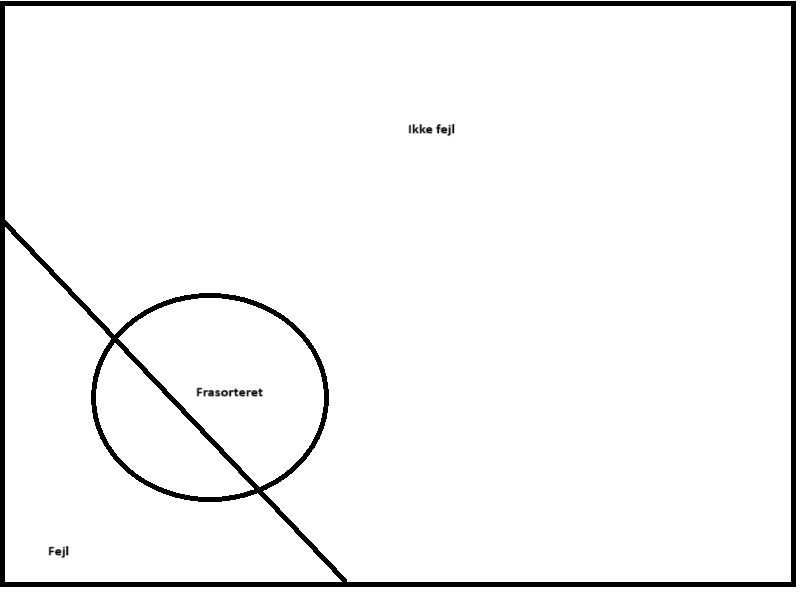

fejl = 0.10;
ikkefejl = 1-fejl;

frasorteret = 0.12;
ikkefrasorteret = 1-frasorteret;

fejlGivetFrasorteret = 0.68;


**b) Find med visning af mellemregninger sandsynligheden for, at et ikke-frasorteret emne efter inspektionen indeholder fejl?**

$\Pr \left(\mathrm{fejl}\cap \overline{\mathrm{frasorteret}} \right)=\Pr \left(\mathrm{fejl}\right)-\Pr \left(\mathrm{fejl}\cap \mathrm{frasorteret}\right)$ <=>

$\Pr \left(\mathrm{fejl}|\overline{\mathrm{frasorteret}} \right)*\Pr \left(\overline{\mathrm{frasorteret}} \right)=\Pr \left(\mathrm{fejl}\right)-\Pr \left(\mathrm{fejl}|\mathrm{frasorteret}\right)*\Pr \left(\mathrm{frasorteret}\right)$<=>


$$\Pr \left(\mathrm{fejl}|\overline{\mathrm{frasorteret}} \right)=\frac{\Pr \left(\mathrm{fejl}\right)-\Pr \left(\mathrm{fejl}|\mathrm{frasortet}\right)*\Pr \left(\mathrm{frasorteret}\right)}{\Pr \left(\overline{\mathrm{frasorteret}} \right)}$$


fejlGivetIkkeFrasorteret = (fejl - fejlGivetFrasorteret * frasorteret)/ikkefrasorteret

fejlGivetIkkeFrasorteret = 0.0209

**c) Hvad er inspektionssystemets sensitivitet (sandsynligheden for at systemet frasorterer et emne givet, at der er fejl på emnet) og specificitete (sandsynligheden for at systemet ikke frasorterer et emne givet, at der ikke er fejl på emnet)?**

Sensitivitet: $\Pr \left(\mathrm{frasorteret}|\mathrm{fejl}\right)$

Specificitet: $\Pr \left(\overline{\mathrm{frasorteret}} |\overline{\mathrm{fejl}} \right)$

Til sensitiviteten kan vi bruge Bayes regel til at vende vores $\Pr \left(\mathrm{fejl}|\mathrm{frasorteret}\right)$ om til $\Pr \left(\mathrm{frasorteret}|\mathrm{fejl}\right)$


$$\Pr \left(\mathrm{frasorteret}|\mathrm{fejl}\right)=\frac{\Pr \left(\mathrm{fejl}|\mathrm{frasorteret}\right)*\Pr \left(\mathrm{frasorteret}\right)}{\Pr \left(\mathrm{fejl}\right)}$$


sensitivitet = (fejlGivetFrasorteret*frasorteret) / fejl

sensitivitet = 0.8160

Specificitet kan også findes ved hjælp af Bayes regel men inden skal vi bare finde $\Pr \left(\overline{\mathrm{fejl}} |\overline{\mathrm{frasorteret}} \right)$, den kan vi dog nemt finde med følgende udregning:


$$\Pr \left(\overline{\mathrm{fejl}} |\overline{\mathrm{frasorteret}} \right)=1-\Pr \left(\mathrm{fejl}|\overline{\mathrm{frasorteret}} \right)$$


Herefter følger


$$\Pr \left(\overline{\mathrm{frasorteret}} |\overline{\mathrm{fejl}} \right)=\frac{\Pr \left(\overline{\mathrm{fejl}} |\overline{\mathrm{frasorteret}} \right)*\Pr \left(\overline{\mathrm{frasorteret}} \right)}{\Pr \left(\overline{\mathrm{fejl}} \right)}$$


specificitet = ((1-fejlGivetIkkeFrasorteret)*ikkefrasorteret) / ikkefejl

specificitet = 0.9573

### Opgave 2: Stokastike variable

Den kontinuerte stokastiske variabel X er normalfordelt med X ~ N(10,2)

a) Skitser tæthedsfunktionen fx(x) for X i intervallet x=6 til x=14.

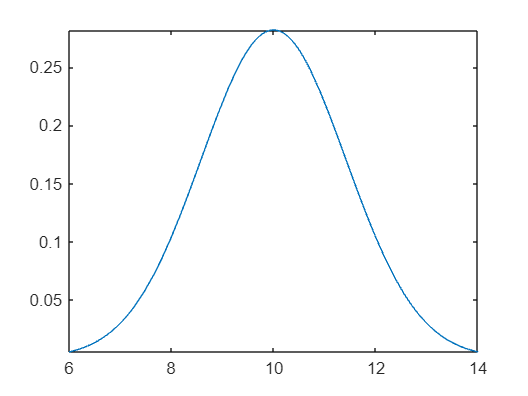

meanx = 10;
varx = 2;
fx = @(x)(1/(sqrt(varx)*sqrt(2*pi)))*exp((-(x-meanx).^2)/(2*varx));
% Could use normpdf with a generated linspace(4, 16, 100)
fplot(fx,[6 14])

b) Opstil udtryk for og beregn sandsynligheden Pr(X < 5)

integral(fx, -inf, 5)

ans = 2.0348e-04

1-integral(fx, 5, inf)

ans = 2.0348e-04

Der er givet en ny variabel Y ~ N(5, $\sigma^2$). Variansen $\sigma^2$ kendes ikke.

c) Kan tæthedsfunktionen (PDF) fy(y) for Y være større end 1 for nogle værdier af y? Begrund svaret.

Da vi ved at arealet under PDF'en skal være lig 1 kan dette godt resultere i, at for nogle værdier kan værdien for Y godt være større end 1. Et eksempel ville være ved en lille varians. Der ville du skulle fordele dit PDF areal indenfor et lille område af værdier.

Vi kan tage eksemplet med formlen for en normal fordelt stokastisk variabel. Hvis vi sætte variansen til noget lavt og giver den en enkelt x værdi burde vi kunne få et tal højere end 1.

varx = 0.1;
fx = @(x)(1/(sqrt(varx)*sqrt(2*pi)))*exp((-(x-meanx).^2)/(2*varx));
fx(10)

ans = 1.2616

Her ses der at fordi vores gennemsnits værdi (stadig som fra før) er 10 og med en varians på 0.1 for vi at værdien bliver over 1.

### Opgave 3: Stokastisk processer

En tidsdiskret stokastisk proces X[n] er givet ved:


$$X\left\lbrack n\right\rbrack =4*Y\left\lbrack n\right\rbrack -Z{\left\lbrack n\right\rbrack }^2$$


Hvor Y[n] ~U[0,4] (Diskret uniform fordeling), Z[n]~U(-3,3), og begge er uafhængige og i.i.d.

a) Tegn 3 realiseringer af X[n] ved tidsstemplerne n= 1, 2, ..., 10. Vis med kode, hvordan realiseringerne er fremkommet.

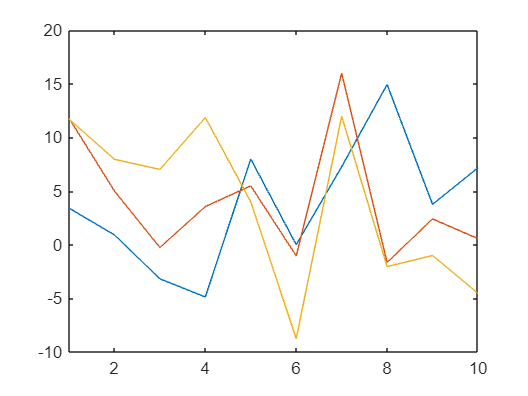

n = linspace(1,10,10);

reals = zeros(3, length(n));
for i=1:length(reals(:,1))
    x = @(n)4*randi([0 4]) - (rand()*6 - 3)^2;
    for j=n
        reals(i,j) = x(j);
    end
end

for i=1:length(reals(:,1))
    plot(n, reals(i,:))
    xlim([1, 10])
    hold on;
end
hold off;

b) Med visning af mellemregninger bestem ensemble middelværdien og ensemble variansen af X[n].


$$E\left\lbrack X\right\rbrack =E\left\lbrack 4*Y\right\rbrack -E\left\lbrack Z^2 \right\rbrack$$


Givet at Y er en diskret uniform fordeling og Z er en kontinuer uniform fordeling kan vi finde følgende middelværdier


$$E\left\lbrack 4*Y\right\rbrack =4*\frac{a+b}{2}=4*\frac{0+4}{2}=4*\frac{4}{2}=4*2=8$$



$$E\left\lbrack Z^2 \right\rbrack =\mathrm{Var}\left(Z\right)+E{\left\lbrack Z\right\rbrack }^2$$



$$\mathrm{Var}\left(Z\right)=\frac{1}{12}*{\left(b-a\right)}^2 =\frac{1}{12}*{\left(-3-3\right)}^2 =\frac{1}{12}*-6^2 =\frac{36}{12}=3$$



$$E\left\lbrack Z\right\rbrack =\frac{1}{2}*\left(a+b\right)=\frac{1}{2}*\left(-3+3\right)=\frac{1}{2}*0=0$$



$$E\left\lbrack Z^2 \right\rbrack =3+0=3$$


EX = 8 - 3

EX = 5


$$\mathrm{Var}\left(X\right)=4*\mathrm{Var}\left(Y\right)-\mathrm{Var}\left(Z^2 \right)$$


Givet at Y er diskret og Z er kontinuer uniforme fordelinger, har vi også følgende værdier for deres varianser


$$\mathrm{Var}\left(Y\right)=\frac{{\left(b-a+1\right)}^2 -1}{12}=\frac{{\left(4-0+1\right)}^2 -1}{12}=\frac{{\left(5\right)}^2 -1}{12}=\frac{24}{12}=2$$


$\mathrm{Var}\left(Z^2 \right)=E\left\lbrack Z^4 \right\rbrack -E{\left\lbrack Z^2 \right\rbrack }^2$ <- brug den her og gang det ud

%mere L.O.T.U.S.

Den Temporale middelværdi og temporale varianse er hhv. XiT = 5 og var(Xi) = 39,2.

c) Er processen X[n] WSS (Wide sense stationary) og er den ergodisk? Begrund dit svar.

For at processen kan være ergodisk skal vi først se om processen er WSS.

Ved at kigge på processen kan vi se, at der ikke er noget i ligningen der er afhængigt af tiden og dermed er processen WSS.

Da vi fra før har ensemble middelværdi og varianse kan vi bruge de værdier samt de temporale værdier til at se om processen er ergodisk.

Fordi at ensemble middelværdi og varianse er lig den temporale middelværdi og varians kan vi se at processen er ergodisk.

WSS: ja

Ergodisk: ja

### Opgave 4: Statistik